# EGH445 Modern Control - Nonlinear Systems and Linearisation

**Topic:** Simulating Linear and Nonlinear Systems

**Example 1: **Consider a single link robotic arm with input torque $T(t)$ (see Fig. 1). Consider the nonlinear and linearised system model (see lecture slides). 

This example will **simulate the system dynamics** for both systems highlighting the differences when nonlinearities are considered. This helps show how 'good' the linearisation process is at capturing the dynamics. Play with the **initial conditions **and set **control input** to analyse behaviour.

*Reference**:* *This example has been adapted from material presented in EGH445 Lecture - Linear Systems and Linearisation.*

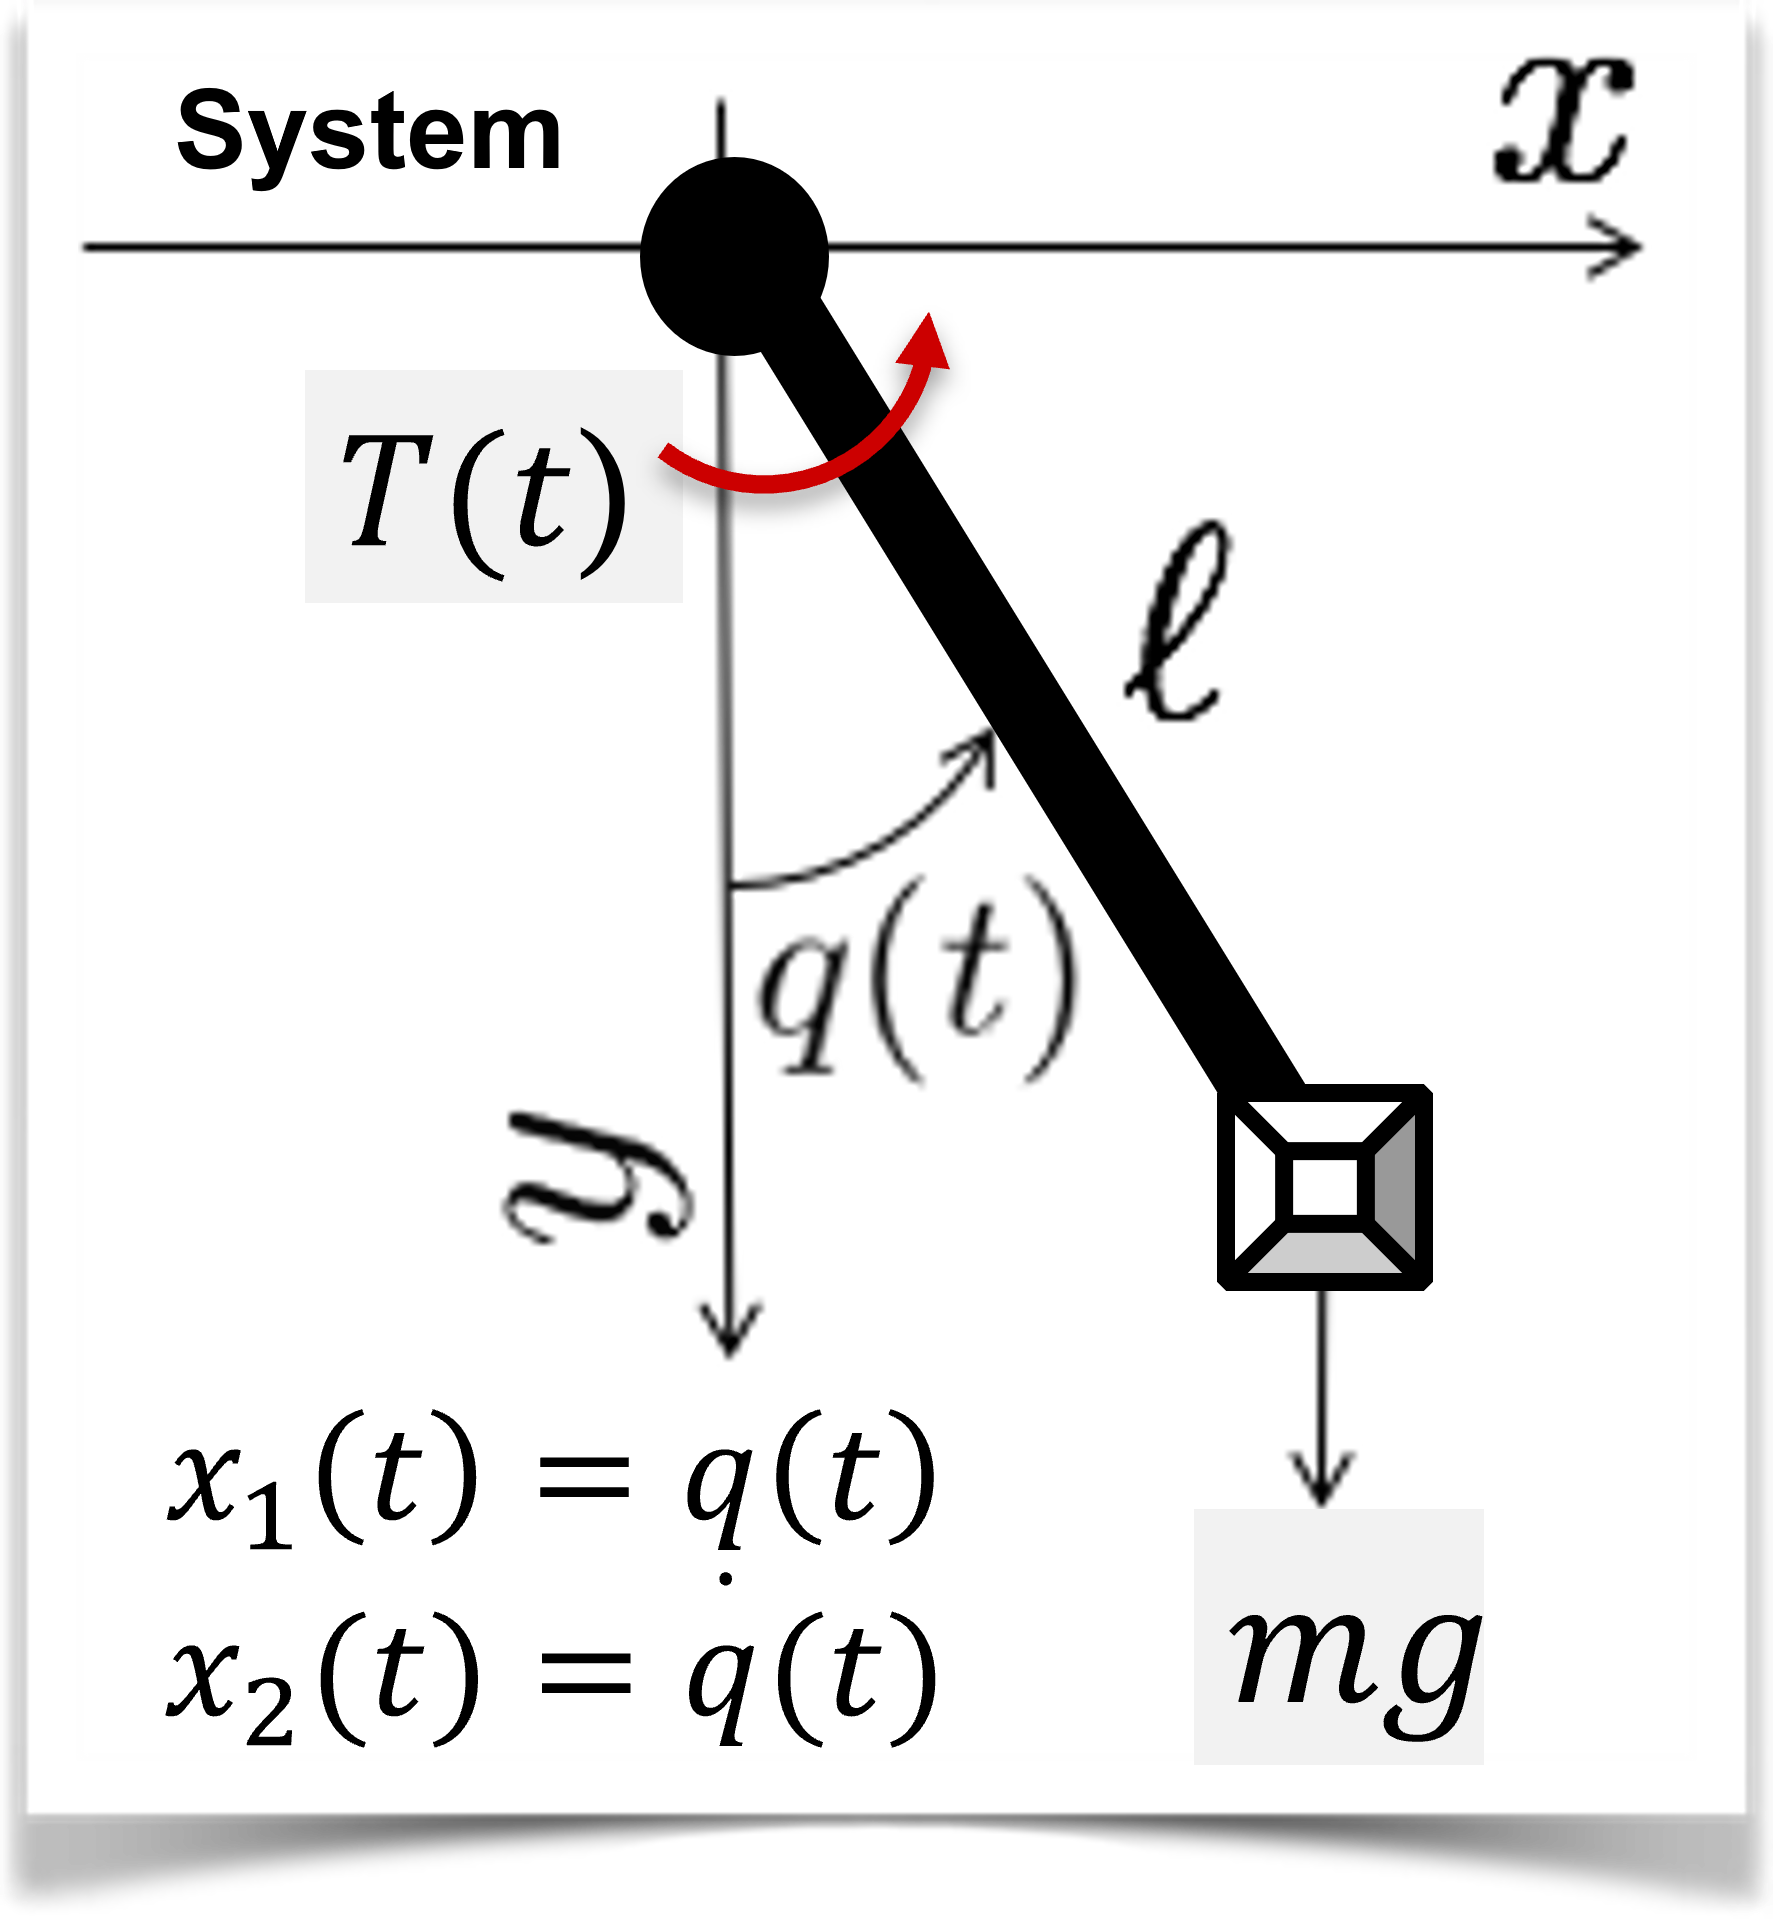

Fig. 1. Robot Arm Example (single link)

clear all; close all; clc

Define the **system parameters** (globally)

global m b l g

m=0.5;
b=0.3; 
l=0.4;
g=9.81;

Define time vectors to allow **input/control**

ut = linspace(0,15,25);
u = (g/l)*sin(pi/4).*ones(numel(ut),1); % Constant input

Define the **system dynamics** using a function

% Define Leaf Spring Dynamics 
function [xdot] = robotarm(t,x,ut,u,flag)

global m b l g

Tq = interp1(ut,u,t); % Evaluate control at time t

if flag % Nonlinear Model
    xdot(1) = x(2);
    xdot(2) = -(g/l)*sin(x(1))-(b/(m*l^2)*x(2) + Tq) ;
    xdot = xdot';
else % Linear Model (Equilibrium Point 3)
    xdot(1) = x(2);
    xdot(2) = -(g/l)*(sqrt(2)/2)*x(1)-(b/(m*l^2)*x(2)) + Tq ;
    xdot = xdot';
end

end

Simulate the system using an appropriate** numerical solver (integrator)**

% Initial Conditions
x0 = [-pi/2 1/(2*pi)];

opts = odeset('RelTol',1e-2,'AbsTol',1e-4);

flag = 0;
[T,x]=ode45(@(t,x) robotarm(t,x,ut,u,flag), [0 15], x0,opts);   % Linear (Robot Arm)
flag = 1;
[T1,x1]=ode45(@(t,x) robotarm(t,x,ut,u,flag), [0 15], x0,opts);   % Nonlinear (Robot Arm)

Plot the **system time responses** after** initial displacement**

x1=rad2deg(x1);
x = rad2deg(x);

figure(1);clf;
title('Time Response'); hold on
subplot(211); hold on
title('Time Response');
plot(T,x(:,1),'b--');
plot(T1,x1(:,1),'r--');
legend('Linear','Nonlinear')
ylabel('q (deg)','Interpreter','Latex','FontSize',8)
xlabel('Time','FontSize',8)

subplot(212); hold on
title('Time Response');
plot(T,x(:,2),'b-');
plot(T1,x1(:,2),'r-');
legend('Linear','Nonlinear')
ylabel('$\dot{q}$ (deg/s)','Interpreter','Latex','FontSize',8)
xlabel('Time','FontSize',8)
%text(4,0.3,['k 2=',num2str(k2)],'FontSize',8)

Plot the **state trajectories** after** initial displacement**

figure(2);clf;
title('State Trajectory'); hold on
%subplot(211); hold on
plot(x(:,1),x(:,2),'b--');
plot(x1(:,1),x1(:,2),'r--');
legend('Linear','Nonlinear')
xlabel('$q$ (deg)','Interpreter','Latex','FontSize',8)
ylabel('$\dot{q}$ (deg/s)','Interpreter','Latex','FontSize',8)

**Example 2:** Consider a **mass spring** **system** used to model a mass at the end of a spring. The **linear system dynamics** are such that the spring 'bounces' the mass. Assuming the displacement of the mass $x$ is the system state, the dynamics can be described by:


$$m\ddot{x}(t) = -k_1x(t) -b\dot{x}(t)$$


Consider the** leaf spring system** used on some car suspension systems (See Fig 2). The **nonlinear system dynamics** are such that the spring becomes stiffer the more it deflects. Assuming the displacement of the mass $x$ is the system state, the dynamics can be described by:


$$m\ddot{x}(t) = -k_1x(t) -k_2x(t)^3-b\dot{x}(t)$$


For both systems, $m$ is the mass, $k_1$ and $k_2$ are constants related to the spring materials/setup and $b$ is a damping force (due friction etc.). Assuming$x_1$ (displacement) and $x_2$ (velocity) are the system sates, both systems have an equilibrium point at $x_1=0$ and $x_2=0$ such that the system is stationary. The leaf spring system resembles the mass spring system when $k_2=0$ and thus become linear in this case.

This example will **simulate the system dynamic**s for both systems highlighting the differences when nonlinearities are considered. This helps show the difference between** real and theoretical** systems.

*Reference**:* *This example has been adapted from material presented in *[*16.30/31 5–13 Feedback Control Systems, Topic 5*](https://ocw.mit.edu/courses/16-30-feedback-control-systems-fall-2010/1bfc976fcead1982d90c5057511e5ef7_MIT16_30F10_lec05.pdf#:~:text=What%20are%20state-space%20models%3F%20Why%20should%20we%20use,state-space%20model%2C%20and%20how%20do%20we%20analyze%20these%3F)* provided by MIT OpenCourseWear *

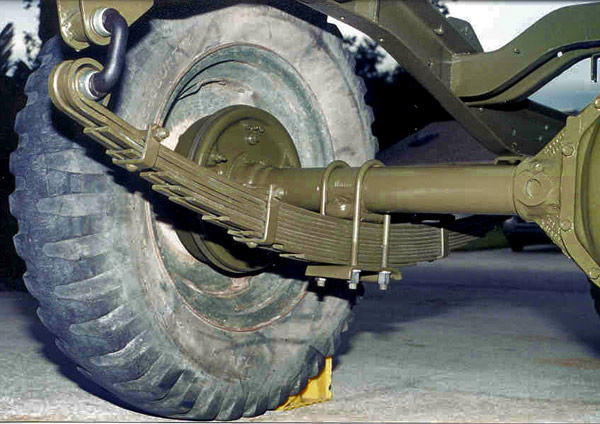

Fig. 2 Leaf Spring System ([http://en.wikipedia.org/wiki/Image:Leafs1.jpg.](http://en.wikipedia.org/wiki/Image:Leafs1.jpg.))

clear all; close all; clc

Define the system parameters (globally)

global m k1 k2 b

m = 1;
b = 0.1;

Define the system dynamics using a function

% Define Leaf Spring Dynamics 
function [xdot] = leafspring(t,x)

global m k1 k2 b
xdot(1) = x(2);
xdot(2) = (-k1*x(1)-k2*(x(1))^3 -b*x(2))/m;
xdot = xdot';
end

Simulate the system using an appropriate** numerical solver (integrator)**


x0 = [-3 2]/10;
k1=1;k2=0;
[T,x]=ode23(@leafspring, [0 40], x0);   % Linear (Mass Spring)

k2=-2;
[T1,x1]=ode23(@leafspring, [0 40], x0); % Nonlinear (Leaf Spring)

Plot the **system time responses** after** initial displacement**

figure(1);clf;
title('State Evolution')
subplot(211); hold on
plot(T,x(:,1),'b--');
plot(T1,x1(:,1),'r--');
legend('Linear','Nonlinear')
ylabel('x','Interpreter','Latex','FontSize',8)
xlabel('Time','FontSize',8)

subplot(212); hold on
plot(T,x(:,2),'b-');
plot(T1,x1(:,2),'r-');
legend('Linear','Nonlinear')
ylabel('$\dot{x}$','Interpreter','Latex','FontSize',8)
xlabel('Time','FontSize',8)
text(4,0.3,['k 2=',num2str(k2)],'FontSize',8)

Plot the **state trajectories** after** initial displacement**

figure(2);clf;
title('State Trajectory'); hold on
%subplot(211); hold on
plot(x(:,1),x(:,2),'b--');
plot(x1(:,1),x1(:,2),'r--');
legend('Linear','Nonlinear')
xlabel('$x_1$','Interpreter','Latex','FontSize',8)
ylabel('$x_2$','Interpreter','Latex','FontSize',8)